if sum(c0avr)==0
    semilogx(pivavr1_norm1024,'g--');hold on;semilogx(pibavr1_norm1024,'r-.');semilogx(pitavr_norm1024,'k');semilogx(cavr_norm1024,'b');
   else
    semilogx(pivavr1_norm1024,'g--');hold on;semilogx(pibavr1_norm1024,'r-.');semilogx(pitavr_norm1024,'k');semilogx(cavr_norm1024+c0avr_norm1024,'b');
 end
y_ref(1:482)=0.5;
semilogx(y_ref,'--k');
%add 0.5 reference
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
h=legend('$\langle \overline \Pi(k)\rangle$','$\langle \overline \Pi^u(k)\rangle$',...
    '$\langle\overline \Pi^b(k)\rangle$'...
    ,'$\langle\overline {S}_{ij}\overline{B}_i\overline{B}_j(k)\rangle$');
set(h,'FontSize',10,'Interpreter','latex');
ylim([-0.1 1.1]);
set(gca,'YTick',(0:0.2:1));
set(gcf,'WindowStyle','normal')
xlabel('$k$','FontSize',10,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.1);
dim = [.45 .5 .3 .3];
str = 'Run IV_c';
annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
legend boxoff;

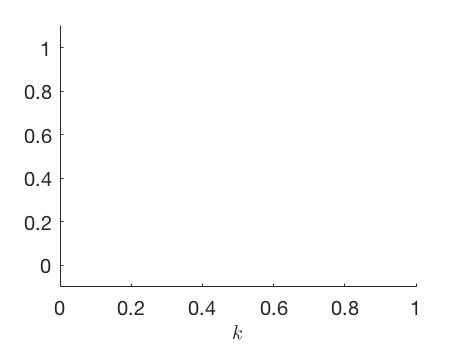

%%figure 2
set(gcf,'WindowStyle','normal')
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
set(gca,'YTick',(0:0.2:1));

xlabel('$k$','FontSize',12,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.1);
legend boxoff;

legend_handle=legend('{Run $\rm III_a$}','{Run $\rm III_b$}','{Run $\rm III_c$}','Location', 'Best');
set(legend_handle,'Interpreter','latex','fontsize',11)
xlabel('$k$','Interpreter','latex','fontsize',12)
ylim([-0.1 1.1])

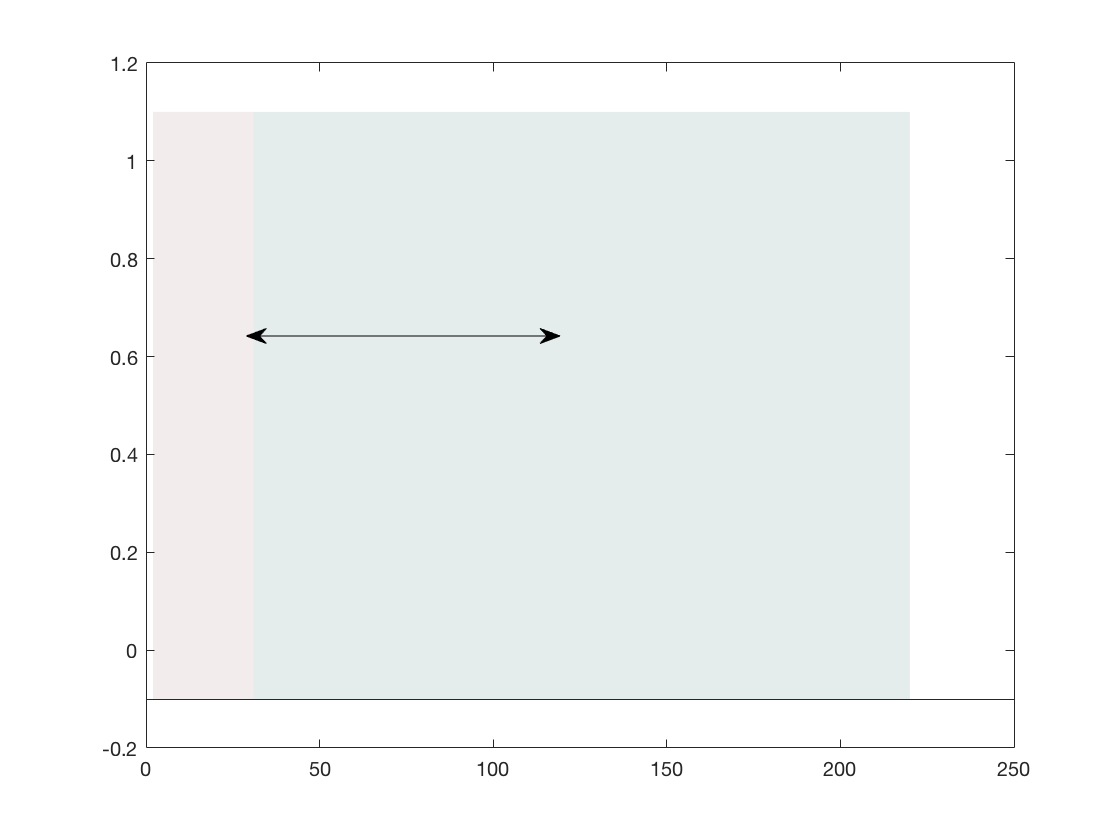

%% this code use for insert shaded region
% figure;
%abcb0 ha = area([1 31], [1.1 1.1]);
conrange=[2 31];
satrange=[31 250];
ha = area(conrange, [1.1 1.1],'BaseValue',-0.1,'AlignVertexCenters','off','LineStyle','none');
ha.FaceAlpha = 0.1;
%ha.FaceColor = [0. 0.25 0.25];
ha.FaceColor = [1 0. 0.];
hold on
ha = area(satrange, [1.1 1.1],'BaseValue',-0.1,'AlignVertexCenters','off','LineStyle','none');
ha.FaceAlpha = 0.1;
%ha.FaceColor = [0. 0.25 0.25];
ha.FaceColor = [0. 0. 1];
%insert double arrow
x = [0.22 0.5];
y = [0.6 0.6];
a = annotation('doublearrow',x,y);


x = [0.55 0.75];
y = [0.6 0.6];
a = annotation('doublearrow',x,y);

specb_cum = cumsum(specbavr);
spece_cum = cumsum(speceavr);
spectot_cum = cumsum(spectot);
loglog(spece_cum, 'g--');hold on;
loglog(specb_cum,'r-.');
loglog(spectot_cum,'k');
hold off;
legend_handle=legend('{$\mathcal{E}_u$}','{$\mathcal{E}_b$}','{$\mathcal{E}_{tot}$}');
set(legend_handle,'Interpreter','latex','fontsize',11,'location','best')
xlabel('$k$','Interpreter','latex','fontsize',10)
%ylabel('$E(k)$','Interpreter','latex','fontsize',12)
xlim([1 1000])

%set(findobj(0,'type','figure'),'visible','on');
set(gcf,'WindowStyle','normal');
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
set(gca,'ylabel',[]);
set(gcf,'WindowStyle','normal')
ylim([10^-2 2])
xlabel('$k$','FontSize',10,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.0);
legend boxoff;


dim = [.35 .2 .2 .2];
str = 'Run II_c';
annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
legend boxoff;

%spectrum
fig = gcf;
clear title xlabel ylabel legend
loglog(speceavr, 'g--');hold on;loglog(specbavr,'r-.');loglog(spectot,'k');loglog(testy1,'b--');loglog(testy2,'k--');hold off;
legend_handle=legend('{$E_u$}','{$E_b$}','{$E_{tot}$}');
set(legend_handle,'Interpreter','latex','fontsize',11,'location','southwest')
xlabel('$k$','Interpreter','latex','fontsize',10)
%ylabel('$E(k)$','Interpreter','latex','fontsize',12)
%ylim([10^-8 1])

set(findobj(0,'type','figure'),'visible','on');
set(gcf,'WindowStyle','normal');
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 3.2, 2.4])
set(gca,'ylabel',[]);
set(gcf,'WindowStyle','normal')
ylim([10^-8 1])
xlabel('$k$','FontSize',10,'Interpreter','latex')
set(findall(gca, 'Type', 'Line'),'LineWidth',1.0);
legend boxoff;


dim = [.6 .2 .2 .2];
str = 'Run I_c';
annotation('textbox',dim,'String',str,'FitBoxToText','on','LineStyle','none');
legend boxoff;